# Classification Tree on the Set of Scores

AUTHOR: Kambadur Ananthamurthy

MAIN PROBLEM STATEMENT: Develop perspectives to understand the scores of the various methods.

close all
%clear

tic

input.nCells = 135;
input.nAlgos = 8;
input.nMethods = 6;

workingOnServer = 1;

if workingOnServer == 1 %Bebinca
    % Synthetic Dataset Details
    input.gDate = 20210824; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210918; %consolidation date
    input.cRun = 1; %consolidation run number
    
elseif workingOnServer == 2 %Adama
    % Synthetic Dataset Details
    input.gDate = 20210903; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210911; %consolidation date
    input.cRun = 1; %consolidation run number
end

workingOnServer = 0;
diaryOn         = 0;


% Directory config

if workingOnServer == 1
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    saveDirec = strcat(HOME_DIR, 'Work/Analysis/Imaging/');
elseif workingOnServer == 2
    HOME_DIR = '/home/ananth/Documents/';
    HOME_DIR2 = '/home/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
end
%Additinal search paths
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/CustomFunctions')))
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/localCopies')))
make_db

saveFolder = strcat(saveDirec, db.mouseName, '/', db.date, '/');

if diaryOn
    if workingOnServer == 1
        diary (strcat(HOME_DIR, '/logs/benchmarksDiary'))
    else
        diary (strcat(HOME_DIR2, '/logs/benchmarksDiary_', num2str(gDate), '_', num2str(gRun)))
    end
    diary on
end


% Operations
plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

% Synthetic Dataset Details
input.gDate = 20210824; %generation date
input.gRun = 1; %generation run number
input.nDatasets = 333;

% Consolidated Analysis Details
input.cDate = 20210918; %consolidation date
input.cRun = 1; %consolidation run number

workingOnServer = 0;
diaryOn         = 0;

% Load Synthetic Data
disp('Loading synthetic datasets ...')

Loading synthetic datasets ...


synthDataFilePath = sprintf('%s/synthDATA_%i_gRun%i_batch_%i.mat', ...
    saveFolder, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets);
load(synthDataFilePath)
disp('... done!')

... done!


% Load Analysis Results
disp('Loading analysis results ...')

Loading analysis results ...


analysisFilePath = sprintf('%s/synthDATA_Analysis_%i_cRun%i_cData.mat', ...
    saveFolder, ...
    input.cDate, ...
    input.cRun);
load(analysisFilePath)
disp('... done!')

... done!



input.removeNaNs = 0;
input.saveFolder = saveFolder;


%Prepare the Look Up Table (LUT)
[response, predictor] = getTheTable(sdo_batch, cData, input);

Creating Look Up Table ...
... done!



%Normalize
maxima = max(predictor);
normPredictor = predictor./maxima;

%Z-Score
zPredictor = zscore(predictor);

% Normalize Z-Score
maxima = max(zPredictor);
nzPredictor = zPredictor./maxima;

% Preprocessing
Z = zPredictor(:, 1:5); % One can try using any of the other normalized or standardized versions

## Graphs

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |    0.010522 |      0.1898 |    0.010522 |    0.010522 |          770 |
|    2 | Best   |    0.010077 |     0.21877 |    0.010077 |    0.010299 |           44 |
|    3 | Accept |     0.49436 |     0.11975 |    0.010077 |    0.010138 |        21350 |


Mdl =   ClassificationTree
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 44955
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


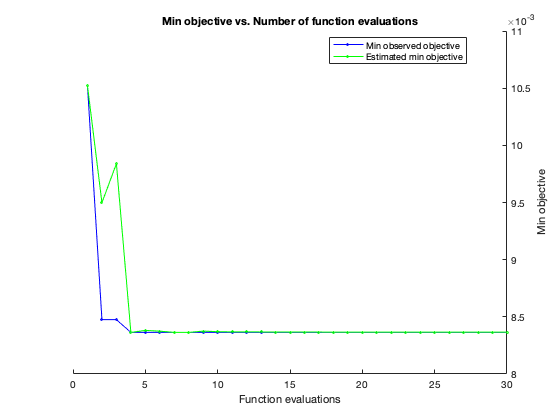

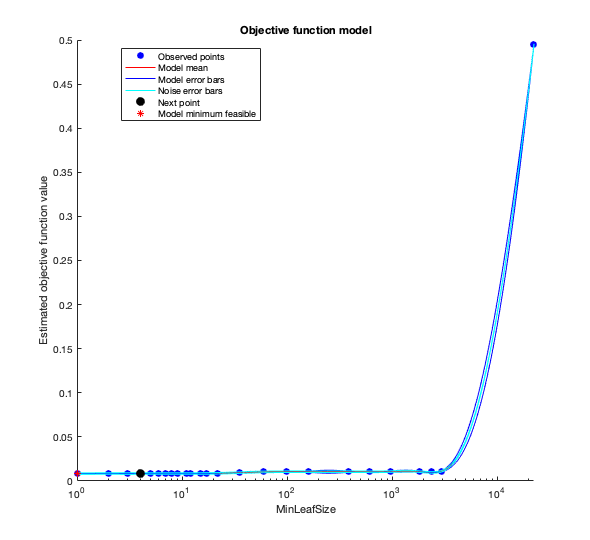

% Mdl = fitctree(Z, response, ...
%     'OptimizeHyperparameters','auto', ...
%     'Prune','on', ...
%     'ScoreTransform', 'logit', ...
%     'Holdout', 0.3)
% Mdl = fitctree(Z, response, ...
%     'OptimizeHyperparameters','auto', ...
%     'Prune','on', ...
%     'ScoreTransform', 'logit', ...
%     'CrossVal','on')
Mdl = fitctree(Z, response, ...
    'OptimizeHyperparameters','auto')

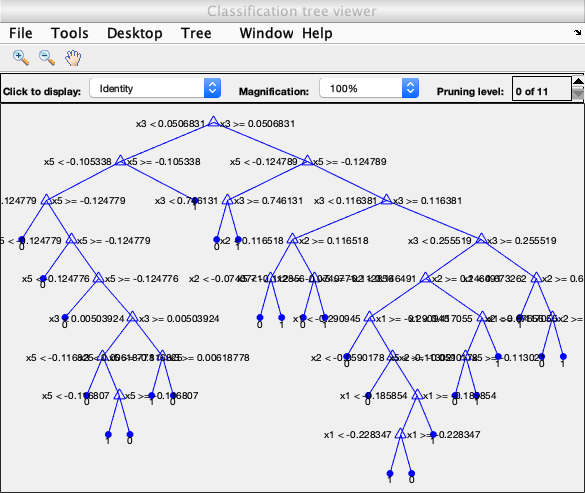

view(Mdl,'Mode','graph') %As a graph

%view(Mdl,'Mode','text') %As text